# (a) 2D Transient diffusion equation:(Gauss-seidel method)

#  
$${\frac{\delta{u}}{\delta{t}}}+\frac{\delta^2{u}}{\delta{x^2}}{(x,y)}+\frac{\delta^2{u}}{\delta{y^2}}{(x,y)}=0$$


Forward difference formula is used in time and Central difference formula in space.

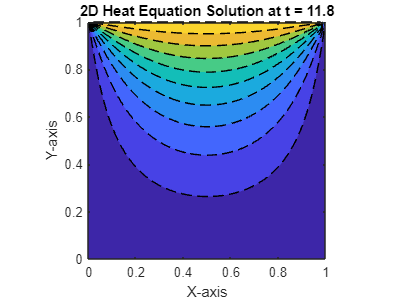


clearvars

% Parameters
Lx = 1.0;         % Length of the domain in x
Ly = 1.0;         % Length of the domain in y
Nx = 51;          % Number of grid points in x
Ny = 51;          % Number of grid points in y
dx = Lx / (Nx - 1); % Grid spacing in x
dy = Ly / (Ny - 1); % Grid spacing in y
x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);
[X, Y] = meshgrid(x, y);

% Boundary conditions
u = zeros(Nx, Ny);
u(:, 1) = 0;        % u(x,0) = 0
u(:, Ny) = 1;       % u(x,1) = 1
u(1, :) = 0;        % u(0,y) = 0
u(Nx, :) = 0;       % u(1,y) = 0

% Time-stepping loop (transient solve) using Gauss-Seidel
max_time =15; % Total simulation time
dt = 0.001;    % Time step

% Number of time steps
timesteps = round(max_time / dt);

for step = 1:timesteps
    max_change = 0;
    for i = 2:Nx-1
        for j = 2:Ny-1
            Laplacian = u(i+1, j) + u(i-1, j) + u(i, j+1) + u(i, j-1) - 4 * u(i, j);
            u_old = u(i, j);
            u(i, j) = u(i, j) + dt * Laplacian / (dx);
            max_change = max(max_change, abs(u_old - u(i, j)));
        end
    end
    
    % Visualize the solution at certain time steps
    if mod(step, 100) == 0
        contourf(X, Y, u', '--');
        xlabel('X-axis');
        ylabel('Y-axis');
        title(['2D Heat Equation Solution at t = ' num2str(step * dt)]);
        axis equal;
        pause(0.01); % Pause to show the plot
    end
    
    % Check for convergence
    if max_change < 1e-6
        break;
    end
end